# Mockup of Intro to proposed ciCamera Class

ciCamera is one of a set of classes that allow experimentation with computational imaging more directly than the previous "lower-level" scene, oi, sensor, and ip structs. Along with ciScene and ciCModule they provide a programmable wrapper that allows users to create "cameras" that have a variety of algorithms for deciding how to capture a scene, and then how to process one or more captures, potentially even from more than one camera module (ciCModule).

History: Initial Code: D. Cardinal 12/2020

ieInit();
ourCamera = ciBurstCamera(); % probably will pass init args
ourCamera.cmodule = ciCModule(); % default
ourCamera.isp = ipCreate(); % default, maybe:)

Now we'll define our scene

scenePath = 'Cornell_BoxBunnyChart';        
sceneName = 'cornell box bunny chart';
ourScene = ciScene('pbrt', scenePath, sceneName);

Read 11 materials
Read 3 textures
Reading C4D geometry information.


optionally set camera and object motion here through parameters/methods of ourScene. 

This sets the Stanford bunny in motion with a vertical movement of about 5cm/s (?) and a tiny rotation.

ourScene.objectMotion = {{'Default_B', [0, 5, 0], [1, 1, 1]}};

For the simplest case we ask our camera to take a picture. By deault it uses the 'Auto' intent. Using 'Burst' will capture more frames if the camera type we are using supports it:

Read 11 materials
Read 3 textures
Reading C4D geometry information.
New light added.
Reading multispectral data with raw data.
Read 11 materials
Read 3 textures
Reading C4D geometry information.
New light added.
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\EIA1956-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\USAF1951-300dpi.png
Copying C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart\macbeth.png
Copied resources from:
C:\iset\iset3d\data\V3\Cornell_BoxBunnyChart 
to 
C:\iset\iset3d\local\Cornell_BoxBunnyChart 
 
Overwriting PBRT file C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts.pbrt
Material file Cornell_Box_Multiple_Cameras_Bunny_charts_materials.pbrt written successfully.
C:\iset\iset3d\local\Cornell_BoxBunnyChart\Cornell_Box_Multiple_Cameras_Bunny_charts_geometry.pbrt is written out 
Docker container vistalab/pbrt-v3-spectral:latest
Docker command
	docker run -ti --rm -w /Cornell_BoxBunnyChart -v C:/iset/iset3d/local/Cor

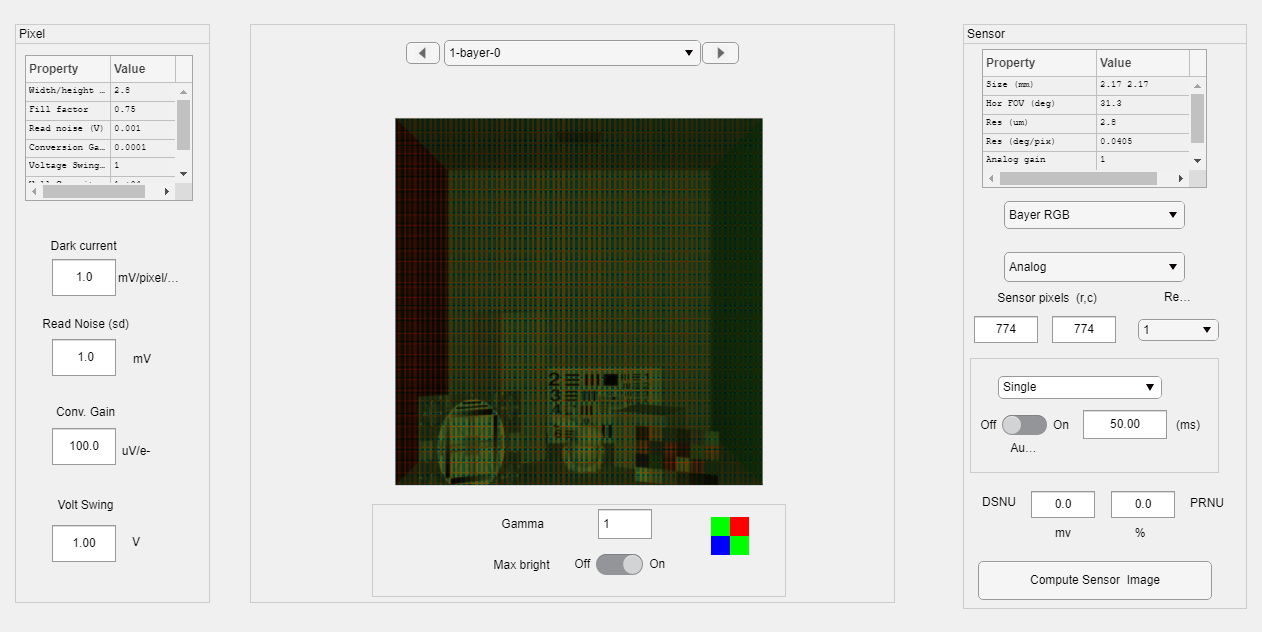

Reference to non-existent field 'compute'.

Error in ciCamera/TakePicture (line 82)
                ourPicture = obj.isp.compute(sensorImages(ii));

Error in ciBurstCamera/TakePicture (line 19)
            ourPicture = TakePicture@ciCamera(obj, scene, intent);

finalImage = ourCamera.TakePicture(ourScene, 'Burst');

ipWindow(finalImage); % let's see what we got